# WBR系统建模分析

## 1 系统建模

### 1.1 简化与假设

(1) 机器人简化为机体、左右腿、左右驱动轮5部分组成的刚体系统

(2) 忽略腿部连杆机构运动（包括腿长变化，惯量变化）产生的动力学效应，即任意时刻均将腿部视为该时刻腿长对应参数的刚体

(3) 忽略腿部、机体位形变化对z轴转动惯量的影响

(4) 假设驱动轮与地面间无滑动（后续会加入离地/打滑检测）

(5) 滚转角roll（$\psi$）通过腿部控制器进行控制，在机器人整体动力学分析中假设 $\psi=\dot\psi=\ddot\psi=0$

(6) 腿部支持力通过腿部控制器进行控制，在机器人整体动力学分析中假设左右腿支持力保持相等，忽略侧向惯性力矩的影响。

### 1.2 变量、参数定义

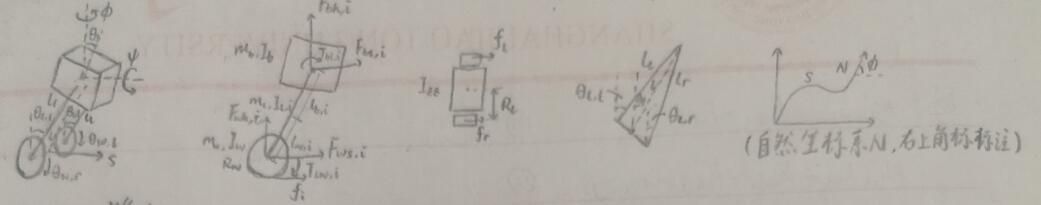

**变量（标有*号的为独立变量）**

*$\theta_{w,i}\ (i=l,r)$: 驱动轮转角（自然坐标系法向）

*$\theta_{l,i}\ (i=l,r)$: 腿倾斜角（自然坐标系法向）

*$\theta_b$: 机体倾斜角（自然坐标系法向）

$\phi$: 偏航角，yaw

$s$: 自然坐标系下机器人水平方向移动距离

$s_b$: 自然坐标系下机体质心水平方向移动距离

$h_b$: 自然坐标系下机体质心竖直方向移动距离

$s_{l,i}\ (i=l,r)$: 自然坐标系下腿部质心水平方向移动距离

$h__{l,i}\ (i=l,r)$: 自然坐标系下腿部质心竖直方向移动距离

*$T__{w,i}\ (i=l,r)$: 驱动轮转矩（腿-轮）

*$T__{b,i}\ (i=l,r)$: 腿部转矩（机体-腿）

$f_i\ (i=l,r)$: 地面对驱动轮摩擦力

$F__{ws,i}\ (i=l,r)$: 驱动轮对腿水平方向作用力

$F__{wh,i}\ (i=l,r)$: 驱动轮对腿竖直方向作用力

$F__{bs,i}\ (i=l,r)$: 腿对机体水平方向作用力

$F__{bh,i}\ (i=l,r)$: 腿对机体竖直方向作用力

**参数**

$R_w$: 驱动轮半径

$R_l$: 驱动轮轮距/2

$l_i\ (i=l,r)$: 腿长*1

$l_{w,i}\ (i=l,r)$: 驱动轮到腿部质心距离*1

$l_{b,i}\ (i=l,r)$: 驱动轮到腿部质心距离*1

$l_c$: 机体质心到腿部关节距离

$m_w$: 驱动轮质量

$m_l$: 腿部质量

$m_b$: 机体质量

$I_w$: 驱动轮转动惯量（自然坐标系法向）

$I_{l,i}$: 腿部转动惯量（自然坐标系法向）*1

$I_b$: 机体转动惯量（自然坐标系法向）

$I_z$: 机器人z轴转动惯量*2

**备注**

*1：实际机器人腿部为五连杆机构，腿长可变，长度由腿部控制器控制，且质心位置、转动惯量均随腿长变化。

*2：绕z轴的转动惯量简化为常量。

% gravitational acceleration
g = sym("g");

% robot structure
WBR = struct;

% variables
WBR.theta_wl = sym("theta_w_l");
WBR.theta_wl_D1 = sym("theta_w_l_D1");
WBR.theta_wl_D2 = sym("theta_w_l_D2");

WBR.theta_wr = sym("theta_w_r");
WBR.theta_wr_D1 = sym("theta_w_r_D1");
WBR.theta_wr_D2 = sym("theta_w_r_D2");

WBR.theta_ll = sym("theta_l_l");
WBR.theta_ll_D1 = sym("theta_l_l_D1");
WBR.theta_ll_D2 = sym("theta_l_l_D2");

WBR.theta_lr = sym("theta_l_r");
WBR.theta_lr_D1 = sym("theta_l_r_D1");
WBR.theta_lr_D2 = sym("theta_l_r_D2");

WBR.theta_b = sym("theta_b");
WBR.theta_b_D1 = sym("theta_b_D1");
WBR.theta_b_D2 = sym("theta_b_D2");

WBR.T_lwl = sym("T_lw_l");
WBR.T_lwr = sym("T_lw_r");
WBR.T_bll = sym("T_bl_l");
WBR.T_blr = sym("T_bl_r");

WBR.f_l = sym("f_l");
WBR.f_r = sym("f_r");
WBR.F_wsl = sym("F_ws_l");
WBR.F_wsr = sym("F_ws_r");
WBR.F_whl = sym("F_wh_l");
WBR.F_whr = sym("F_wh_r");
WBR.F_bsl = sym("F_bs_l");
WBR.F_bsr = sym("F_bs_r");
WBR.F_bhl = sym("F_bh_l");
WBR.F_bhr = sym("F_bh_r");

% parameters
WBR.R_w = sym("R_w");
WBR.R_l = sym("R_l");
WBR.l_l = sym("l_l");
WBR.l_r = sym("l_r");
WBR.l_wl = sym("l_w_l");
WBR.l_wr = sym("l_w_r");
WBR.l_bl = sym("l_b_l");
WBR.l_br = sym("l_b_r");
WBR.l_c = sym("l_c");
WBR.m_w = sym("m_w");
WBR.m_l = sym("m_l");
WBR.m_b = sym("m_b");
WBR.I_w = sym("I_w");
WBR.I_ll = sym("I_l_l");
WBR.I_lr = sym("I_l_r");
WBR.I_b = sym("I_b");
WBR.I_z = sym("I_z");

## 2 运动学

根据变量、参数定义和几何关系得到系统的运动学方程，进而解得各变量的表达式

$s=\frac{R_w}{2}(\theta_{w,l}+\theta_{w,r})$    (2.1)

$h_b=\frac{l_l}{2}cos\theta_{l,l}+\frac{l_r}{2}cos\theta_{l,r}$    (2.2)

$s_{l,i}=R_w\theta_{w,i}+l_{w,i}sin\theta_{l,i}$    (2.3)

$h_{l,i}=h_b-l_{b,i}cos\theta_{l,i}$    (2.4)

$R_w\theta_{w,l}=s_b-R_l\phi-l_lsin\theta_{l,l}$    (2.5)

$R_w\theta_{w,r}=s_b+R_l\phi-l_rsin\theta_{l,r}$    (2.6)

联立式 (2.5)(2.6)

$\phi=\frac{R_w}{2R_l}(-\theta_{w,l}+\theta_{w,r})-\frac{l_l}{2R_l}sin\theta_{l,l}+\frac{l_r}{2R_l}sin\theta_{l,r}$    (2.7)

$s_b=\frac{R_w}{2}(\theta_{w,l}+\theta_{w,r})+\frac{l_l}{2}sin\theta_{l,l}+\frac{l_r}{2}sin\theta_{l,r}$    (2.8)

式 (2.1)(2.2)(2.3)(2.4)(2.7)(2.8) 对时间分别求一/二阶导

$\dot{s}=\frac{R_w}{2}(\dot\theta_{w,l}+\dot\theta_{w,r})$    (2.9)

$\ddot{s}=\frac{R_w}{2}(\ddot\theta_{w,l}+\ddot\theta_{w,r})$    (2.10)

$\dot\phi=\frac{R_w}{2R_l}(-\dot\theta_{w,l}+\dot\theta_{w,r})-\frac{l_l}{2R_l}cos\theta_{l,l}\dot\theta_{l,l}+\frac{l_r}{2R_l}cos\theta_{l,r}\dot\theta_{l,r}$    (2.11)

$\ddot\phi=\frac{R_w}{2R_l}(-\ddot\theta_{w,l}+\ddot\theta_{w,r})-\frac{l_l}{2R_l}cos\theta_{l,l}\ddot\theta_{l,l}+\frac{l_r}{2R_l}cos\theta_{l,r}\ddot\theta_{l,r}+\frac{l_l}{2R_l}sin\theta_{l,l}\dot\theta_{l,l}^2-\frac{l_r}{2R_l}sin\theta_{l,r}\dot\theta_{l,r}^2$    (2.12)

$\dot{s}_b=\frac{R_w}{2}(\dot\theta_{w,l}+\dot\theta_{w,r})+\frac{l_l}{2}cos\theta_{l,l}\dot\theta_{l,l}+\frac{l_r}{2}cos\theta_{l,r}\dot\theta_{l,r}$    (2.13)

$\ddot{s}_b=\frac{R_w}{2}(\ddot\theta_{w,l}+\ddot\theta_{w,r})+\frac{l_l}{2}cos\theta_{l,l}\ddot\theta_{l,l}+\frac{l_r}{2}cos\theta_{l,r}\ddot\theta_{l,r}-\frac{l_l}{2}sin\theta_{l,l}\dot\theta_{l,l}^2-\frac{l_r}{2}sin\theta_{l,r}\dot\theta_{l,r}^2$    (2.14)

$\dot{h}_b=-\frac{l_l}{2}sin\theta_{l,l}\dot\theta_{l,l}-\frac{l_r}{2}sin\theta_{l,r}\dot\theta_{l,r}$    (2.15)

$\ddot{h}_b=-\frac{l_l}{2}sin\theta_{l,l}\ddot\theta_{l,l}-\frac{l_r}{2}sin\theta_{l,r}\ddot\theta_{l,r}-\frac{l_l}{2}cos\theta_{l,l}\dot\theta_{l,l}^2-\frac{l_r}{2}cos\theta_{l,r}\dot\theta_{l,r}^2$    (2.16)

$\dot{s}_{l,i}=R_w\dot\theta_{w,i}+l_{w,i}cos\theta_{l,i}\dot\theta_{l,i}$    (2.17)

$\ddot{s}_{l,i}=R_w\ddot\theta_{w,i}+l_{w,i}cos\theta_{l,i}\ddot\theta_{l,i}-l_{w,i}sin\theta_{l,i}\dot\theta_{l,i}^2$    (2.18)

$\dot{h}_{l,i}=\dot{h}_b+l_{b,i}sin\theta_{l,i}\dot\theta_{l,i}$    (2.19)

$\ddot{h}_{l,i}=\ddot{h}_b+l_{b,i}sin\theta_{l,i}\ddot\theta_{l,i}+l_{b,i}cos\theta_{l,i}\dot\theta_{l,i}^2$    (2.20)

% kinemetic
WBR.s = WBR.R_w/2*(WBR.theta_wl+WBR.theta_wr);
WBR.s_D1 = WBR.R_w/2*(WBR.theta_wl_D1+WBR.theta_wr_D1);
WBR.s_D2 = WBR.R_w/2*(WBR.theta_wl_D2+WBR.theta_wr_D2);

WBR.phi = WBR.R_w/(2*WBR.R_l)*(-WBR.theta_wl+WBR.theta_wr) ...
         -WBR.l_l/(2*WBR.R_l)*sin(WBR.theta_ll) ...
         +WBR.l_r/(2*WBR.R_l)*sin(WBR.theta_lr);
WBR.phi_D1 = WBR.R_w/(2*WBR.R_l)*(-WBR.theta_wl_D1+WBR.theta_wr_D1) ...
            -WBR.l_l/(2*WBR.R_l)*cos(WBR.theta_ll)*WBR.theta_ll_D1 ...
            +WBR.l_r/(2*WBR.R_l)*cos(WBR.theta_lr)*WBR.theta_lr_D1;
WBR.phi_D2 = WBR.R_w/(2*WBR.R_l)*(-WBR.theta_wl_D2+WBR.theta_wr_D2) ...
            -WBR.l_l/(2*WBR.R_l)*cos(WBR.theta_ll)*WBR.theta_ll_D2 ...
            +WBR.l_r/(2*WBR.R_l)*cos(WBR.theta_lr)*WBR.theta_lr_D2 ...
            -WBR.l_l/(2*WBR.R_l)*sin(WBR.theta_ll)*WBR.theta_ll_D1^2 ...
            +WBR.l_r/(2*WBR.R_l)*sin(WBR.theta_lr)*WBR.theta_lr_D1^2;

WBR.s_b = WBR.R_w/2*(WBR.theta_wl+WBR.theta_wr) ...
         +WBR.l_l/2*sin(WBR.theta_ll)+WBR.l_r/2*sin(WBR.theta_lr);
WBR.s_b_D1 = WBR.R_w/2*(WBR.theta_wl_D1+WBR.theta_wr_D1) ...
            +WBR.l_l/2*cos(WBR.theta_ll)*WBR.theta_ll_D1 ...
            +WBR.l_r/2*cos(WBR.theta_lr)*WBR.theta_lr_D1;
WBR.s_b_D2 = WBR.R_w/2*(WBR.theta_wl_D2+WBR.theta_wr_D2) ...
            +WBR.l_l/2*cos(WBR.theta_ll)*WBR.theta_ll_D2 ...
            +WBR.l_r/2*cos(WBR.theta_lr)*WBR.theta_lr_D2 ...
            -WBR.l_l/2*sin(WBR.theta_ll)*WBR.theta_ll_D1^2 ...
            -WBR.l_r/2*sin(WBR.theta_lr)*WBR.theta_lr_D1^2;

WBR.h_b = WBR.l_l/2*cos(WBR.theta_ll)+WBR.l_r/2*cos(WBR.theta_lr);
WBR.h_b_D1 = -WBR.l_l/2*sin(WBR.theta_ll)*WBR.theta_ll_D1 ...
             -WBR.l_r/2*sin(WBR.theta_lr)*WBR.theta_lr_D1;
WBR.h_b_D2 = -WBR.l_l/2*sin(WBR.theta_ll)*WBR.theta_ll_D2 ...
             -WBR.l_r/2*sin(WBR.theta_lr)*WBR.theta_lr_D2 ...
             -WBR.l_l/2*cos(WBR.theta_ll)*WBR.theta_ll_D1^2 ...
             -WBR.l_r/2*cos(WBR.theta_lr)*WBR.theta_lr_D1^2;

WBR.s_ll = WBR.R_w*WBR.theta_wl+WBR.l_wl*sin(WBR.theta_ll);
WBR.s_ll_D1 = WBR.R_w*WBR.theta_wl_D1 ...
             +WBR.l_wl*cos(WBR.theta_ll)*WBR.theta_ll_D1;
WBR.s_ll_D2 = WBR.R_w*WBR.theta_wl_D2+ ...
             +WBR.l_wl*cos(WBR.theta_ll)*WBR.theta_ll_D2 ...
             -WBR.l_wl*sin(WBR.theta_ll)*WBR.theta_ll_D1^2;

WBR.s_lr = WBR.R_w*WBR.theta_wr+WBR.l_wr*sin(WBR.theta_lr);
WBR.s_lr_D1 = WBR.R_w*WBR.theta_wr_D1 ...
             +WBR.l_wr*cos(WBR.theta_lr)*WBR.theta_lr_D1;
WBR.s_lr_D2 = WBR.R_w*WBR.theta_wr_D2+ ...
             +WBR.l_wr*cos(WBR.theta_lr)*WBR.theta_lr_D2 ...
             -WBR.l_wr*sin(WBR.theta_lr)*WBR.theta_lr_D1^2;

WBR.h_ll = WBR.h_b-WBR.l_bl*cos(WBR.theta_ll);
WBR.h_ll_D1 = WBR.h_b_D1+WBR.l_bl*sin(WBR.theta_ll)*WBR.theta_ll_D1;
WBR.h_ll_D2 = WBR.h_b_D2 ...
             +WBR.l_bl*sin(WBR.theta_ll)*WBR.theta_ll_D2 ...
             +WBR.l_bl*cos(WBR.theta_ll)*WBR.theta_ll_D1^2;

WBR.h_lr = WBR.h_b-WBR.l_br*cos(WBR.theta_lr);
WBR.h_lr_D1 = WBR.h_b_D1+WBR.l_br*sin(WBR.theta_lr)*WBR.theta_lr_D1;
WBR.h_lr_D2 = WBR.h_b_D2 ...
             +WBR.l_br*sin(WBR.theta_lr)*WBR.theta_lr_D2 ...
             +WBR.l_br*cos(WBR.theta_lr)*WBR.theta_lr_D1^2;

## 3 动力学

### 3.1 动力学方程

使用牛顿欧拉法建立系统的动力学方程

对于左右驱动轮 $(i=l,r)$

$m_wR_w\ddot\theta_{w,i}=f_i-F_{ws,i}$    (3.1)

$I_w\ddot\theta_{w,i}=T_{lw,i}-f_iR_w$    (3.2)

对于左右腿 $(i=l,r)$

$m_l\ddot{s}_{l,i}=F_{ws,i}-F_{bs,i}$    (3.3)

$m_l\ddot{h}_{l,i}=F_{wh,i}-F_{bh,i}-m_lg$    (3.4)

$I_{l,i}\ddot\theta_{l,i}=(F_{wh,i}l_{w,i}+F_{bh,i}l_{b,i})sin\theta_{l,i}-(F_{ws,i}l_{w,i}+F_{bs,i}l_{b,i})cos\theta_{l,i}-T_{lw,i}+T_{bl,i}$    (3.5)

对于机体

$m_b\ddot{s}_b=F_{bs,l}+F_{bs,r}$    (3.6)

$m_b\ddot{h}_b=F_{bh,l}+F_{bh,r}-m_bg$    (3.7)

$I_b\ddot\theta_b=-(T_{bl,l}+T_{bl,r})-(F_{bs,l}+F_{bs,r})l_ccos\theta_b+(F_{bh,l}+F_{bh,r})l_csin\theta_b$    (3.8)

机器人整体偏航（yaw）方向旋转

$I_z\ddot\phi=(-f_l+f_r)R_l$    (3.9)

左右腿支持力相等

$F_{wh,l}=F_{wh,r}$    （3.10）

### 3.2 方程求解

将式 (2.1)~(2.4)，(2.7)~(2.20) 带入式 (3.1)~(3.10) ，分析动力学方程组，共有15个未知量（5个广义坐标的二阶导数+10个约束力），15个独立方程（关于未知量线性），方程组有唯一解。

% % dynamics equations
% WBR.dyn_eq = sym("eq",[15,1]);
% % left wheel
% WBR.dyn_eq(1) = WBR.f_l-WBR.F_wsl-WBR.m_w*WBR.R_w*WBR.theta_wl_D2;
% WBR.dyn_eq(2) = WBR.T_lwl-WBR.f_l*WBR.R_w-WBR.I_w*WBR.theta_wl_D2;
% % right wheel
% WBR.dyn_eq(3) = WBR.f_r-WBR.F_wsr-WBR.m_w*WBR.R_w*WBR.theta_wr_D2;
% WBR.dyn_eq(4) = WBR.T_lwr-WBR.f_r*WBR.R_w-WBR.I_w*WBR.theta_wr_D2;
% % left leg
% WBR.dyn_eq(5) = WBR.F_wsl-WBR.F_bsl-WBR.m_l*WBR.s_ll_D2;
% WBR.dyn_eq(6) = WBR.F_whl-WBR.F_bhl-WBR.m_l*g-WBR.m_l*WBR.h_ll_D2;
% WBR.dyn_eq(7) = (WBR.F_whl*WBR.l_wl+WBR.F_bhl*WBR.l_bl)*sin(WBR.theta_ll) ...
%                -(WBR.F_wsl*WBR.l_wl+WBR.F_bsl*WBR.l_bl)*cos(WBR.theta_ll) ...
%                -WBR.T_lwl+WBR.T_bll-WBR.I_ll*WBR.theta_ll_D2;
% % right leg
% WBR.dyn_eq(8) = WBR.F_wsr-WBR.F_bsr-WBR.m_l*WBR.s_lr_D2;
% WBR.dyn_eq(9) = WBR.F_whr-WBR.F_bhr-WBR.m_l*g-WBR.m_l*WBR.h_lr_D2;
% WBR.dyn_eq(10) = (WBR.F_whr*WBR.l_wr+WBR.F_bhr*WBR.l_br)*sin(WBR.theta_lr) ...
%                 -(WBR.F_wsr*WBR.l_wr+WBR.F_bsr*WBR.l_br)*cos(WBR.theta_lr) ...
%                 -WBR.T_lwr+WBR.T_blr-WBR.I_lr*WBR.theta_lr_D2;
% % body
% WBR.dyn_eq(11) = WBR.F_bsl+WBR.F_bsr-WBR.m_b*WBR.s_b_D2;
% WBR.dyn_eq(12) = WBR.F_bhl+WBR.F_bhr-WBR.m_b*g-WBR.m_b*WBR.h_b_D2;
% WBR.dyn_eq(13) = -(WBR.T_bll+WBR.T_blr) ...
%                  -(WBR.F_bsl+WBR.F_bsr)*WBR.l_c*cos(WBR.theta_b) ...
%                  +(WBR.F_bhl+WBR.F_bhr)*WBR.l_c*sin(WBR.theta_b) ...
%                  -WBR.I_b*WBR.theta_b_D2;
% % yaw rotation
% WBR.dyn_eq(14) = (-WBR.f_l+WBR.f_r)*WBR.R_l-WBR.I_z*WBR.phi_D2;
% % support force
% WBR.dyn_eq(15) = WBR.F_whl-WBR.F_whr;
% 
% % solve equation
% [WBR.f_l,WBR.F_wsl] = solve([WBR.dyn_eq(1),WBR.dyn_eq(2)], ...
%                             [WBR.f_l,WBR.F_wsl]);
% [WBR.f_r,WBR.F_wsr] = solve([WBR.dyn_eq(3),WBR.dyn_eq(4)], ...
%                             [WBR.f_r,WBR.F_wsr]);
% 
% [WBR.F_bsl,WBR.F_bsr] = solve([WBR.dyn_eq(5),WBR.dyn_eq(8)], ...
%                               [WBR.F_bsl,WBR.F_bsr]);
% WBR.F_bsl = subs(WBR.F_bsl,{sym("f_l"),sym("F_ws_l")}, ...
%                          {WBR.f_l,WBR.F_wsl});
% WBR.F_bsr = subs(WBR.F_bsr,{sym("f_r"),sym("F_ws_r")}, ...
%                          {WBR.f_r,WBR.F_wsr});
% 
% [WBR.F_whl,WBR.F_whr,WBR.F_bhl,WBR.F_bhr] = solve( ...
%   [WBR.dyn_eq(6),WBR.dyn_eq(9),WBR.dyn_eq(12),WBR.dyn_eq(15)], ...
%   [WBR.F_whl,WBR.F_whr,WBR.F_bhl,WBR.F_bhr]);
% WBR.F_whl = subs(WBR.F_whl, ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr});
% WBR.F_whr = subs(WBR.F_whr, ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr});
% WBR.F_bhl = subs(WBR.F_bhl, ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr});
% WBR.F_bhr = subs(WBR.F_bhr, ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr});
% 
% WBR.dyn_eq(7) = simplify(subs(WBR.dyn_eq(7), ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r"), ...
%    sym("F_wh_l"),sym("F_wh_r"),sym("F_bh_l"),sym("F_bh_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr, ...
%    WBR.F_whl,WBR.F_whr,WBR.F_bhl,WBR.F_bhr}));
% WBR.dyn_eq(10) = simplify(subs(WBR.dyn_eq(10), ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r"), ...
%    sym("F_wh_l"),sym("F_wh_r"),sym("F_bh_l"),sym("F_bh_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr, ...
%    WBR.F_whl,WBR.F_whr,WBR.F_bhl,WBR.F_bhr}));
% WBR.dyn_eq(11) = simplify(subs(WBR.dyn_eq(11), ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r"), ...
%    sym("F_wh_l"),sym("F_wh_r"),sym("F_bh_l"),sym("F_bh_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr, ...
%    WBR.F_whl,WBR.F_whr,WBR.F_bhl,WBR.F_bhr}));
% WBR.dyn_eq(13) = simplify(subs(WBR.dyn_eq(13), ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r"), ...
%    sym("F_wh_l"),sym("F_wh_r"),sym("F_bh_l"),sym("F_bh_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr, ...
%    WBR.F_whl,WBR.F_whr,WBR.F_bhl,WBR.F_bhr}));
% WBR.dyn_eq(14) = simplify(subs(WBR.dyn_eq(14), ...
%   {sym("f_l"),sym("f_r"), ...
%    sym("F_ws_l"),sym("F_ws_r"),sym("F_bs_l"),sym("F_bs_r"), ...
%    sym("F_wh_l"),sym("F_wh_r"),sym("F_bh_l"),sym("F_bh_r")}, ...
%   {WBR.f_l,WBR.f_r,WBR.F_wsl,WBR.F_wsr,WBR.F_bsl,WBR.F_bsr, ...
%    WBR.F_whl,WBR.F_whr,WBR.F_bhl,WBR.F_bhr}));
% 
% % approximation
% WBR.dyn_eq = subs(WBR.dyn_eq, ...
%                  {sin(WBR.theta_ll)^2,sin(WBR.theta_ll),cos(WBR.theta_ll)}, ...
%                  {0,WBR.theta_ll,1});
% WBR.dyn_eq = subs(WBR.dyn_eq, ...
%                  {sin(WBR.theta_lr)^2,sin(WBR.theta_lr),cos(WBR.theta_lr)}, ...
%                  {0,WBR.theta_lr,1});
% WBR.dyn_eq = subs(WBR.dyn_eq, ...
%                  {sin(WBR.theta_b)^2,sin(WBR.theta_b),cos(WBR.theta_b)}, ...
%                  {0,WBR.theta_b,1});
% WBR.dyn_eq = subs(WBR.dyn_eq, ...
%                  {WBR.theta_ll^2,WBR.theta_lr^2,WBR.theta_b^2, ...
%                   WBR.theta_ll*WBR.theta_lr, ...
%                   WBR.theta_ll_D1^2,WBR.theta_lr_D1^2,WBR.theta_b_D1^2,}, ...
%                  {0,0,0,0,0,0,0});
% 
% % unable to solve
% % [WBR.theta_wl_D2,WBR.theta_wr_D2,WBR.theta_ll_D2,WBR.theta_lr_D2,WBR.theta_b_D2] = solve( ...
% %   [WBR.dyn_eq(7),WBR.dyn_eq(10),WBR.dyn_eq(11),WBR.dyn_eq(13),WBR.dyn_eq(14)], ...
% %   [WBR.theta_wl_D2,WBR.theta_wr_D2,WBR.theta_ll_D2,WBR.theta_lr_D2,WBR.theta_b_D2]);

消去约束力，并对腿部、机体倾角进行小角度近似，得到如下方程组

$(I_w\frac{l_l}{R_w}+m_wR_wl_l+m_lR_wl_{b,l})\ddot\theta__{w,l}+(m_ll_{w,l}l_{b,l}-I_{l,l})\ddot\theta_{l,l}+(m_ll_{w,l}+\frac{1}{2}m_bl_l)g\theta_{l,l}+T_{bl,l}-T_{lw,l}(1+\frac{l_l}{R_w})
=0$    (3.11)

$(I_w\frac{l_r}{R_w}+m_wR_wl_r+m_lR_wl_{b,r})\ddot\theta__{w,r}+(m_ll_{w,r}l_{b,r}-I_{l,r})\ddot\theta_{l,r}+(m_ll_{w,r}+\frac{1}{2}m_bl_r)g\theta_{l,r}+T_{bl,r}-T_{lw,r}(1+\frac{l_r}{R_w})
=0$    (3.12)

$-(m_wR_w^2+I_w+m_lR_w^2+\frac{1}{2}m_bR_w^2)\ddot\theta_{w,l}-(m_wR_w^2+I_w+m_lR_w^2+\frac{1}{2}m_bR_w^2)\ddot\theta_{w,r}-(m_lR_wl_{w,l}+\frac{1}{2}m_bR_wl_l)\ddot\theta_{l,l}-(m_lR_wl_{w,r}+\frac{1}{2}m_bR_wl_r)\ddot\theta_{l,r}+T_{lw,l}+T_{lw,r}
=0$    (3.13)

$(m_wR_wl_c+I_w\frac{l_c}{R_w}+m_lR_wl_c)\ddot\theta_{w,l}+(m_wR_wl_c+I_w\frac{l_c}{R_w}+m_lR_wl_c)\ddot\theta_{w,r}+m_ll_{w,l}l_c\ddot\theta_{l,l}+m_ll_{w,r}l_c\ddot\theta_{l,r}-I_b\ddot\theta_{l,r}+m_bgl_c\theta_b-(T_{lw,l}+T_{lw,r})\frac{l_c}{R_w}-(T_{bl,l}+T_{bl,r})
=0$    (3.14)

$(\frac{1}{2}I_z\frac{R_w}{R_l}+I_w\frac{R_l}{R_w})\ddot\theta_{w,l}-(\frac{1}{2}I_z\frac{R_w}{R_l}+I_w\frac{R_l}{R_w})\ddot\theta_{w,r}+\frac{1}{2}I_z\frac{l_l}{R_l}\ddot\theta_{l,l}-\frac{1}{2}I_z\frac{l_r}{R_l}\ddot\theta_{l,r}-T_{lw,l}\frac{R_l}{R_w}+T_{lw,r}\frac{R_l}{R_w}
=0$    (3.15)

% solve dynamic equation
WBR.dyn_eq = sym("eq",[5,1]);
WBR.dyn_eq(1) = (WBR.I_w*WBR.l_l/WBR.R_w+WBR.m_w*WBR.R_w*WBR.l_bl ...
                   +WBR.m_l*WBR.R_w*WBR.l_bl)*WBR.theta_wl_D2 ...
               +(WBR.m_l*WBR.l_wl*WBR.l_bl-WBR.I_ll)*WBR.theta_ll_D2 ...
               +(WBR.m_l*WBR.l_wl+WBR.m_b*WBR.l_l/2)*g*WBR.theta_ll ...
               +WBR.T_bll-WBR.T_lwl*(1+WBR.l_l/WBR.R_w);
WBR.dyn_eq(2) = (WBR.I_w*WBR.l_r/WBR.R_w+WBR.m_w*WBR.R_w*WBR.l_br ...
                   +WBR.m_l*WBR.R_w*WBR.l_br)*WBR.theta_wr_D2 ...
               +(WBR.m_l*WBR.l_wr*WBR.l_br-WBR.I_lr)*WBR.theta_lr_D2 ...
               +(WBR.m_l*WBR.l_wr+WBR.m_b*WBR.l_r/2)*g*WBR.theta_lr ...
               +WBR.T_blr-WBR.T_lwr*(1+WBR.l_r/WBR.R_w);
WBR.dyn_eq(3) = -(WBR.m_w*WBR.R_w^2+WBR.I_w+WBR.m_l*WBR.R_w^2 ...
                    +WBR.m_b*WBR.R_w^2/2)*WBR.theta_wl_D2 ...
                -(WBR.m_w*WBR.R_w^2+WBR.I_w+WBR.m_l*WBR.R_w^2 ...
                    +WBR.m_b*WBR.R_w^2/2)*WBR.theta_wr_D2 ...
                -(WBR.m_l*WBR.R_w*WBR.l_wl+WBR.m_b*WBR.R_w*WBR.l_l) ...
                    *WBR.theta_ll_D2 ...
                -(WBR.m_l*WBR.R_w*WBR.l_wr+WBR.m_b*WBR.R_w*WBR.l_r) ...
                    *WBR.theta_lr_D2 ...
                +WBR.T_lwl+WBR.T_lwr;
WBR.dyn_eq(4) = (WBR.m_w*WBR.R_w+WBR.I_w/WBR.R_w+WBR.m_l*WBR.R_w) ...
                   *WBR.l_c*(WBR.theta_wl_D2+WBR.theta_wr_D2) ...
               +WBR.m_l*WBR.l_wl*WBR.l_c*WBR.theta_ll_D2 ...
               +WBR.m_l*WBR.l_wr*WBR.l_c*WBR.theta_lr_D2 ...
               -WBR.I_b*WBR.theta_b_D2+WBR.m_b*g*WBR.l_c*WBR.theta_b ...
               -(WBR.T_lwl+WBR.T_lwr)*WBR.l_c/WBR.R_w ...
               -(WBR.T_bll+WBR.T_blr);
WBR.dyn_eq(5) = (WBR.I_z*WBR.R_w/(2*WBR.R_l)+WBR.I_w*WBR.R_l/WBR.R_w) ...
                   *(WBR.theta_wl_D2-WBR.theta_wr_D2) ...
               +WBR.I_z*WBR.l_l/(2*WBR.R_l)*WBR.theta_ll_D2 ...
               -WBR.I_z*WBR.l_r/(2*WBR.R_l)*WBR.theta_lr_D2 ...
               +(-WBR.T_lwl+WBR.T_lwr)*WBR.R_l/WBR.R_w;
WBR.dyn_sol = solve(WBR.dyn_eq,[WBR.theta_wl_D2,WBR.theta_wr_D2, ...
                                WBR.theta_ll_D2,WBR.theta_lr_D2, ...
                                WBR.theta_b_D2]);

## 4 状态空间模型

状态空间方程

$\left\{\begin{array}{l} 
\mathbf{\dot{x}}=A\mathbf{x}+B\mathbf{u} \\ 
\mathbf{y}=C\mathbf{x}
\end{array}$    (4.1)

式 (4.1) 中

状态向量 $\mathbf{x}=\left[\matrix{
s & \dot{s} & \phi & \dot\phi & \theta_{l,l} & \dot\theta_{l,l} & \theta_{l,r} & \dot\theta_{l,r} & \theta_b & \dot\theta_b
}\right]^T$

控制向量 $\mathbf{u}=\left[\matrix{
T_{lw,l} & T_{lw,r} & T_{bl,l} & T_{bl,r}
}\right]^T$

输出向量 $\mathbf{y}=\mathbf{x}$

$A=\left[\matrix{
0&1&0&0&0&0&0&0&0&0 \cr
0&0&0&0&a_{2,5}&0&a_{2,7}&0&a_{2,9}&0 \cr
0&0&0&1&0&0&0&0&0&0 \cr
0&0&0&0&a_{4,5}&0&a_{4,7}&0&a_{4,9}&0 \cr
0&0&0&0&0&1&0&0&0&0 \cr
0&0&0&0&a_{6,5}&0&a_{6,7}&0&a_{6,9}&0 \cr
0&0&0&0&0&0&0&1&0&0 \cr
0&0&0&0&a_{8,5}&0&a_{8,7}&0&a_{8,9}&0 \cr
0&0&0&0&0&0&0&0&0&1 \cr
0&0&0&0&a_{10,5}&0&a_{10,7}&0&a_{10,9}&0 \cr
}\right]$, $B=\left[\matrix{
0&0&0&0 \cr
b_{2,1}&b_{2,2}&b_{2,3}&b_{2,4} \cr
0&0&0&0 \cr
b_{4,1}&b_{4,2}&b_{4,3}&b_{4,4} \cr
0&0&0&0 \cr
b_{6,1}&b_{6,2}&b_{6,3}&b_{6,4} \cr
0&0&0&0 \cr
b_{8,1}&b_{8,2}&b_{8,3}&b_{8,4} \cr
0&0&0&0 \cr
b_{10,1}&b_{10,2}&b_{10,3}&b_{10,4} \cr
}\right]$, $C =I_{10}$


$$a_{i,j}=\left\{\begin{array}{l}
\frac{R_w}{2}\left(\frac{\partial\ddot\theta_{w,l}}{\partial{x}_j}+\frac{\partial\ddot\theta_{w,r}}{\partial{x}_j}\right) & (i=2) \\
\frac{R_w}{2R_l}\left(-\frac{\partial\ddot\theta_{w,l}}{\partial{x}_j}+\frac{\partial\ddot\theta_{w,r}}{\partial{x}_j}\right)-\frac{l_l}{2R_l}\frac{\partial\ddot\theta_{l,l}}{\partial{x}_j}+\frac{l_r}{2R_l}\frac{\partial\ddot\theta_{l,r}}{\partial{x}_j} & (i=4) \\
\frac{\partial\dot{x}_i}{\partial{x}_j} & (i=6,8,10)
\end{array}$$



$$b_{i,j}=\left\{\begin{array}{l}
\frac{R_w}{2}\left(\frac{\partial\ddot\theta_{w,l}}{\partial{u}_j}+\frac{\partial\ddot\theta_{w,r}}{\partial{u}_j}\right) & (i=2) \\
\frac{R_w}{2R_l}\left(-\frac{\partial\ddot\theta_{w,l}}{\partial{u}_j}+\frac{\partial\ddot\theta_{w,r}}{\partial{u}_j}\right)-\frac{l_l}{2R_l}\frac{\partial\ddot\theta_{l,l}}{\partial{u}_j}+\frac{l_r}{2R_l}\frac{\partial\ddot\theta_{l,r}}{\partial{u}_j} & (i=4) \\
\frac{\partial\dot{x}_i}{\partial{u}_j} & (i=6,8,10)
\end{array}$$


% state space equation
WBR.A = sym(zeros(10,10));
for i = 1:2:9
  WBR.A(i,i+1) = 1;
end
WBR.A(2,5) = WBR.R_w/2*(diff(WBR.dyn_sol.theta_w_l_D2,WBR.theta_ll) ...
                       +diff(WBR.dyn_sol.theta_w_r_D2,WBR.theta_ll));
WBR.A(2,7) = WBR.R_w/2*(diff(WBR.dyn_sol.theta_w_l_D2,WBR.theta_lr) ...
                       +diff(WBR.dyn_sol.theta_w_r_D2,WBR.theta_lr));
WBR.A(2,9) = WBR.R_w/2*(diff(WBR.dyn_sol.theta_w_l_D2,WBR.theta_b) ...
                       +diff(WBR.dyn_sol.theta_w_r_D2,WBR.theta_b));
WBR.A(4,5) = WBR.R_w/(2*WBR.R_l)*(-diff(WBR.dyn_sol.theta_w_l_D2,WBR.theta_ll) ...
                                  +diff(WBR.dyn_sol.theta_w_r_D2,WBR.theta_ll)) ...
            -WBR.l_l/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_l_D2,WBR.theta_ll) ...
            +WBR.l_r/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_r_D2,WBR.theta_ll);
WBR.A(4,7) = WBR.R_w/(2*WBR.R_l)*(-diff(WBR.dyn_sol.theta_w_l_D2,WBR.theta_lr) ...
                                  +diff(WBR.dyn_sol.theta_w_r_D2,WBR.theta_lr)) ...
            -WBR.l_l/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_l_D2,WBR.theta_lr) ...
            +WBR.l_r/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_r_D2,WBR.theta_lr);
WBR.A(4,9) = WBR.R_w/(2*WBR.R_l)*(-diff(WBR.dyn_sol.theta_w_l_D2,WBR.theta_b) ...
                                  +diff(WBR.dyn_sol.theta_w_r_D2,WBR.theta_b)) ...
            -WBR.l_l/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_l_D2,WBR.theta_b) ...
            +WBR.l_r/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_r_D2,WBR.theta_b);
WBR.A(6,5) = diff(WBR.dyn_sol.theta_l_l_D2,WBR.theta_ll);
WBR.A(6,7) = diff(WBR.dyn_sol.theta_l_l_D2,WBR.theta_lr);
WBR.A(6,9) = diff(WBR.dyn_sol.theta_l_l_D2,WBR.theta_b);
WBR.A(8,5) = diff(WBR.dyn_sol.theta_l_r_D2,WBR.theta_ll);
WBR.A(8,7) = diff(WBR.dyn_sol.theta_l_r_D2,WBR.theta_lr);
WBR.A(8,9) = diff(WBR.dyn_sol.theta_l_r_D2,WBR.theta_b);
WBR.A(10,5) = diff(WBR.dyn_sol.theta_b_D2,WBR.theta_ll);
WBR.A(10,7) = diff(WBR.dyn_sol.theta_b_D2,WBR.theta_lr);
WBR.A(10,9) = diff(WBR.dyn_sol.theta_b_D2,WBR.theta_b);

WBR.B = sym(zeros(10,4));
WBR.B(2,1) = WBR.R_w/2*(diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_lwl) ...
                       +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_lwl));
WBR.B(2,2) = WBR.R_w/2*(diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_lwr) ...
                       +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_lwr));
WBR.B(2,3) = WBR.R_w/2*(diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_bll) ...
                       +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_bll));
WBR.B(2,4) = WBR.R_w/2*(diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_blr) ...
                       +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_blr));
WBR.B(4,1) = WBR.R_w/(2*WBR.R_l)*(-diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_lwl) ...
                                  +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_lwl)) ...
            -WBR.l_l/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_lwl) ...
            +WBR.l_r/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_lwl);
WBR.B(4,2) = WBR.R_w/(2*WBR.R_l)*(-diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_lwr) ...
                                  +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_lwr)) ...
            -WBR.l_l/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_lwr) ...
            +WBR.l_r/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_lwr);
WBR.B(4,3) = WBR.R_w/(2*WBR.R_l)*(-diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_bll) ...
                                  +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_bll)) ...
            -WBR.l_l/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_bll) ...
            +WBR.l_r/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_bll);
WBR.B(4,4) = WBR.R_w/(2*WBR.R_l)*(-diff(WBR.dyn_sol.theta_w_l_D2,WBR.T_blr) ...
                                  +diff(WBR.dyn_sol.theta_w_r_D2,WBR.T_blr)) ...
            -WBR.l_l/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_blr) ...
            +WBR.l_r/(2*WBR.R_l)*diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_blr);
WBR.B(6,1) = diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_lwl);
WBR.B(6,2) = diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_lwr);
WBR.B(6,3) = diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_bll);
WBR.B(6,4) = diff(WBR.dyn_sol.theta_l_l_D2,WBR.T_blr);
WBR.B(8,1) = diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_lwl);
WBR.B(8,2) = diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_lwr);
WBR.B(8,3) = diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_bll);
WBR.B(8,4) = diff(WBR.dyn_sol.theta_l_r_D2,WBR.T_blr);
WBR.B(10,1) = diff(WBR.dyn_sol.theta_b_D2,WBR.T_lwl);
WBR.B(10,2) = diff(WBR.dyn_sol.theta_b_D2,WBR.T_lwr);
WBR.B(10,3) = diff(WBR.dyn_sol.theta_b_D2,WBR.T_bll);
WBR.B(10,4) = diff(WBR.dyn_sol.theta_b_D2,WBR.T_blr);